Моделирование оптической системы и обработка данных

clear
close all
clc
tetta = 1000;
modelingMode = 1;% 1 - моделироввние ~30 минут, 0 - не моделирование ~1.5 минуты
pname = 'D:\Turboshaft\разрешение\ledFULL\EXP2.00_1234_LED_TRY1';
[distribution, ligth_start_coordX, ~, flag_opt,res_matrix, error_opt, alpha, regul_param, error, Load_file] = spaceTransformation(pname, modelingMode, tetta);
sum(flag_opt==35)/size(distribution,1)*100
Load_file = Load_file';

figure
[X,Y] = meshgrid(0:120/19:120,450+(0:300/(size(Load_file,1)-1):300));
surf(X,Y,Load_file)

Error using surf (line 71)
Z must be a matrix, not a scalar or vector.

title('Спектр снятый с волокна')
xlabel('номер измерения')
ylabel('длина волны')
xlim([0 120])
ylim([450 750])
figure
surf(X,Y,distribution)
title('Регуляризированный спектр')
xlabel('номер измерения')
ylabel('длина волны')
xlim([0 120])
ylim([450 750])

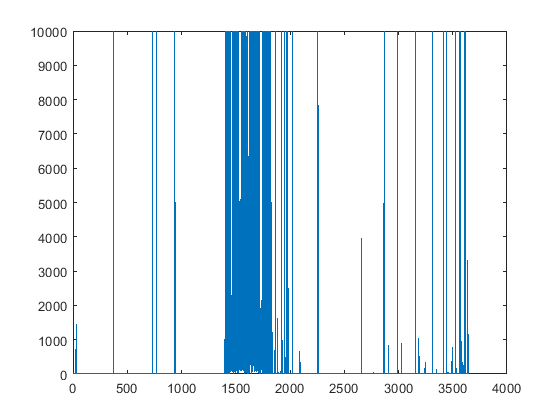

figure
plot(flag_opt)

pname = 'D:\Turboshaft\разрешение\ledFULL\EXP2.00_12345678_LED_TRY1';
oldFolder = cd(pname);
Load_file1 = zeros(20, 3648);
prename = 'AVST_mesurement_';
for i = 1:20
    Load_name = strcat(prename, string(i), '.csv');
    Load_file1(i,:) = load(Load_name);
end
cd(oldFolder)
pname = 'D:\Turboshaft\разрешение\ledFULL\EXP2.00_1234_LED_TRY1';
oldFolder = cd(pname);
Load_file2 = zeros(20, 3648);
prename = 'AVST_mesurement_';
for i = 1:20
    Load_name = strcat(prename, string(i), '.csv');
    Load_file2(i,:) = load(Load_name);
end
Wavelenghts = load('Wavelenghts.csv');
cd(oldFolder)

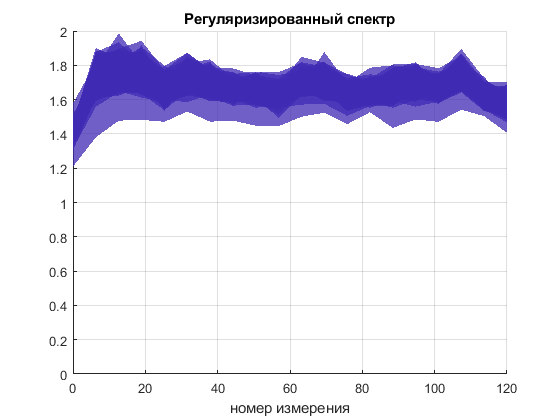

figure
s = surf(X,Y,Load_file1'./Load_file2','FaceAlpha',0.5);
title('Регуляризированный спектр')
xlabel('номер измерения')
ylabel('длина волны')
xlim([0 120])
ylim([580 590])
zlim([0 2])
s.EdgeColor = 'none';
view([0 0])

a = zeros(size(alpha,1),1);
for i = 1:size(alpha,1)
    falpha = alpha(i,:);
    if sum(falpha~=0)~=0
        aalpha = falpha(falpha~=0);
    else
        aalpha = 0;
    end
    a(i) = aalpha(end);
%     hold on
%     if ~isempty(aalpha)
%         plot(error_opt(i,1),aalpha(end),'--gs')
%     end
end
figure
scatter3(a, Wavelenghts, error_opt(:,1));

First_error = error_opt(:,1);
a_for_sort = a(a<20e5);
error_for_sort = First_error(a<20e5);
[serror, Isort] = sort(error_for_sort);
asort = a_for_sort(Isort);

[p,~,mu] = polyfit(serror,asort, 8);
f = polyval(p,serror,[],mu);

figure
grid on
hold on
plot(serror,f)
scatter(serror,asort,'.','MarkerFaceColor','k');

xlim([0 250])
ylim([-279579 2172878])



[~, preAlpha] = min(abs(error_opt(:,1)-serror'),[],2);
test = error_opt(:,1)-serror';


figure
plot(Wavelenghts,flag_opt,'LineWidth',1)
title('Скорость обработки данных','FontSize',25,'FontWeight','bold')
ylabel('Количество итераций, шт.','FontSize',25,'FontWeight','bold')
xlabel('Длина волны, нм','FontSize',25,'FontWeight','bold')

figure
[X,Y] = meshgrid(ligth_start_coordX, Wavelenghts);
mesh(X,Y,distribution,'LineWidth',2)
xlim([ligth_start_coordX(1) ligth_start_coordX(end)])
ylim([Wavelenghts(1) Wavelenghts(end)])
zlim([0 0.09])

title('Разрешенный в пространстве спектр горения газа','FontSize',25,'FontWeight','bold')
xlabel('Координатная ось, мм','FontSize',25,'FontWeight','bold')
ylabel('Длина волны, нм','FontSize',25,'FontWeight','bold')
zlabel('Интенсивность излучения, отн.ед.','FontSize',25,'FontWeight','bold')
figure
[X,Y] = meshgrid(ligth_start_coordX, Wavelenghts);
mesh(X,Y,distribution,'LineWidth',2)
xlim([ligth_start_coordX(1) ligth_start_coordX(end)])
ylim([Wavelenghts(1) Wavelenghts(end)])
% zlim([0 0.09])

title('Разрешенный в пространстве спектр горения газа','FontSize',25,'FontWeight','bold')
xlabel('Координатная ось, мм','FontSize',25,'FontWeight','bold')
ylabel('Длина волны, нм','FontSize',25,'FontWeight','bold')
zlabel('Интенсивность излучения, отн.ед.','FontSize',25,'FontWeight','bold')


figure
[~, C2_medium_ser] = max(distribution(900:1050,1));
plot(ligth_start_coordX,smooth(distribution(C2_medium_ser + 900,:),3),'LineWidth',5)
% title('Интенсивность излучения пика С2(0,0)','FontSize',25,'FontWeight','bold')
xlabel('Координатная ось, мм','FontSize',25,'FontWeight','bold')
ylabel('Интенсивность излучения, отн.ед.','FontSize',25,'FontWeight','bold')
xlim([ligth_start_coordX(1) ligth_start_coordX(end)])
hold on
SKO = sqrt(640);
a = 4.6/(SKO*sqrt(2*pi));
c = SKO;
b = 60;
distribution1 = a * exp(-(ligth_start_coordX - b).^2/(2*c.^2));
plot(ligth_start_coordX,distribution1,'LineWidth',5)
legend('Распределение интенсивности излучения востановленное математическим алгоритмом','Распределение интенсивности излучения горелки Мекера-Фишера','location','best','FontSize',25,'FontWeight','bold')
grid on

% ligth_start_coordX = -ligth_start_coordX(end:-1:1)
figure
[~, C2_medium_ser] = max(distribution(900:1050,1));
plot(ligth_start_coordX,smooth(Load_file(:,2900),1)*0.01,'LineWidth',5)
% title('Интенсивность излучения пика С2(0,0)','FontSize',25,'FontWeight','bold')
xlabel('Координатная ось, мм','FontSize',25,'FontWeight','bold')
ylabel('Интенсивность излучения, отн.ед.','FontSize',25,'FontWeight','bold')
xlim([ligth_start_coordX(1) ligth_start_coordX(end)])
hold on
SKO = sqrt(640);
a = 4.6/(SKO*sqrt(2*pi));
c = SKO;
b = 60;
distribution1 = a * exp(-(ligth_start_coordX - b).^2/(2*c.^2));
plot(ligth_start_coordX,distribution1,'LineWidth',5)
ylim([0 0.1]);
legend('Распределение интенсивности излучения востановленное обратной матрицей','Распределение интенсивности излучения горелки Мекера-Фишера','location','best','FontSize',25,'FontWeight','bold')
grid on


figure
load y1.mat y2
%Диапазон рабочей области 
y_cord = 0:126/(20-1):126;
fiber_cord = zeros(size(y_cord));
for i = 1:length(y_cord)
    [~, fiber_cord(i)] = min(abs(y2 - y_cord(i)));
end
%Диапазон координат волокна
Result_for_matlab = fiber_cord/length(y2).*(366.5-284)+284;
%Добавление ошибки позиционирования
fiber_coord = Result_for_matlab;
[X,Y] = meshgrid(ligth_start_coordX, fiber_coord);

surf(res_matrix, 'EdgeColor','none')
title({'Зависимость интенсивности в волокне от','неравномерного распределения координат в камере сгорания'},'FontSize',25,'FontWeight','bold')
xlabel({'Положение точечного','источника излучения'},'FontSize',25,'FontWeight','bold')
ylabel('Положение волокна','FontSize',25,'FontWeight','bold')
zlabel('Интенсивность излучения, отн.ед.','FontSize',25,'FontWeight','bold')
